## **Name : ____Chatkawin Phongpawarit____**

## Student ID : ___6388041____

## Section : ___2___

# **Triangulation Matting Project **

Read all 4 images

Fg_img1 = imread("fg1.png");
Fg_img2 = imread("fg2.png");
Bg_img1 = imread("bg1.png");
Bg_img2 = imread("bg2.png");

Display all 4 images

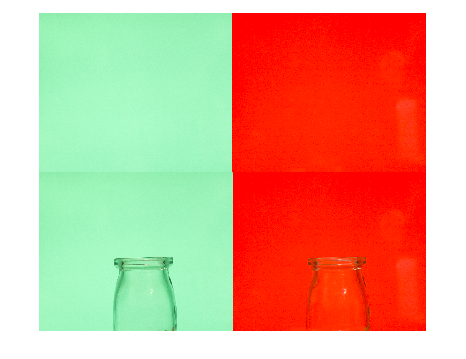

montage({Bg_img1, Bg_img2, Fg_img1, Fg_img2});

Convert to double

Cr1 = Fg_img1(:,:,1); 
Cg1 = Fg_img1(:,:,2); 
Cb1 = Fg_img1(:,:,3); 

Cr2 = Fg_img2(:,:,1); 
Cg2 = Fg_img2(:,:,2); 
Cb2 = Fg_img2(:,:,3);

Br1 = Bg_img1(:,:,1); 
Bg1 = Bg_img1(:,:,2);
Bb1 = Bg_img1(:,:,3);

Br2 = Bg_img2(:,:,1); 
Bg2 = Bg_img2(:,:,2);
Bb2 = Bg_img2(:,:,3);

Cr1 = im2double(Cr1);
Cg1 = im2double(Cg1);
Cb1 = im2double(Cb1);

Cr2 = im2double(Cr2);
Cg2 = im2double(Cg2);
Cb2 = im2double(Cb2);

Br1 = im2double(Br1); 
Bg1 = im2double(Bg1);
Bb1 = im2double(Bb1);

Br2 = im2double(Br2);
Bg2 = im2double(Bg2); 
Bb2 = im2double(Bb2); 

Compute alpha

% up = ((Cr1 - Cr2).*(Br1 - Br2) + (Cg1 - Cg2).*(Bg2 - Bg2) + (Cb1 - Cb2).*(Bb1 - Bb2))
% down = ((Br1 - Br2).^2) + ((Bg1 - Bg2).^2) + ((Bb1 - Bb2).^2)
% alpha = 1 - (up./down)
alpha = 1 - ((((Cr1-Cr2).*(Br1-Br2)) + ((Cg1-Cg2).*(Bg1-Bg2)) + ((Cb1-Cb2).*(Bb1-Bb2)))./(((Br1-Br2).^2) + ((Bg1-Bg2).^2) + ((Bb1-Bb2).^2)));

Compute foreground colors of object from background 1 

Fr1 = (Cr1 - (1-alpha).* Br1) ./ alpha;
Fg1 = (Cg1 - (1-alpha).* Bg1) ./ alpha;
Fb1 = (Cb1 - (1-alpha).* Bb1) ./ alpha;
Fg1(isnan(Fg1)) = 0;
Fg1 = im2gray(Fg1);
Fb1(isnan(Fb1)) = 0;
Fr1(isnan(Fr1)) = 0;
Fr1 = im2gray(Fr1);
Fb1 = im2gray(Fb1);
mat1 = (cat(3,Fr1,Fg1,Fb1));
% mat1(:,:,1) = Fr1;
% mat1(:,:,2) = Fg1;
% mat1(:,:,3) = Fb1;
% 
% mat1 = uint8(mat1);

% Fr1 = uint8(Fr1)
% Fg1 = uint8(Fg1)
% Fb1 = uint8(Fb1)

Compute foreground colors of object from background 2

Fr2 = (Cr2 - (1-alpha).* Br2) ./ alpha;
Fg2 = (Cg2 - (1-alpha).* Bg2) ./ alpha;
Fb2 = (Cb2 - (1-alpha).* Bb2) ./ alpha;
Fr2(isnan(Fr2)) = 0;
Fr2 = im2gray(Fr2);
Fg2(isnan(Fg2)) = 0;
Fg2 = im2gray(Fg2);
Fb2(isnan(Fb2)) = 0;
Fb2 = im2gray(Fb2);
mat2 = (cat(3,Fr2,Fg2,Fb2));

Display the extracted foreground object / matte from background 1 and 2

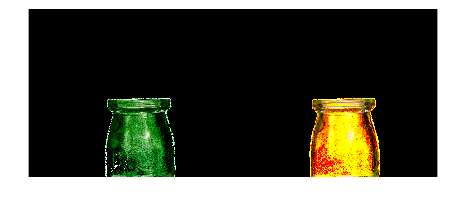

montage({mat1,mat2});

Perform the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

whitebg_green = (alpha .* mat1) + ((1 - alpha) .* ones(720,876));
whitebg_orange = (alpha .* mat2) + ((1 - alpha) .* ones(720,876));
% whitebg_r(:,:) = 255
% whitebg_g(:,:) = 255
% whitebg_b(:,:) = 255
% newwhite_r = alpha .* Fr1 + (1 - alpha) .* whitebg_r;
% newwhite_g = alpha .* Fg1 + (1 - alpha) .* whitebg_g;
% newwhite_b = alpha .* Fb1 + (1 - alpha) .* whitebg_b;


Display the composition of extracted foreground object from background 1 and 2 with the new WHITE background image

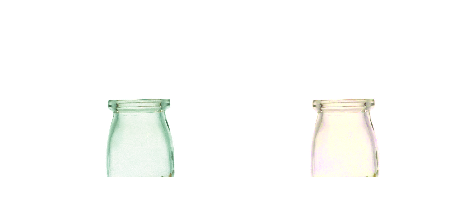

montage({whitebg_green,whitebg_orange});

Read new background image to do the composition and display it.

new_bg = imread("new_bg1.png")

new_bg = 720×876×3 uint8 array
new_bg(:,:,1) =

    90    87    86    86    84    85    85    87    89    89    90    90    90    90    89    88    88    86    85    83    80    80    80    81    81    81    80    80    79    79    78    78    78    78    78    77    76    74    74    72    72    72    73    73    74    74    75    74    75    74    79    81    81    82    82    81    83    83    83    89   100   122   159   186   179   174   207   231   212   198   188   199   220   239   248   253   244   239   244   246   238   225   212   208   223   228   230   232   230   235   244   253   254   252   252   252   252   253   251   251   249   250   252   253   254   254   254   252   250   248   247   246   245   243   240   236   234   231   234   229   221   217   209   204   201   199   195   190   189   187   186   185   189   198   194   167   148   164   160   159   152   133   116   108   100   121   145   145   132   133   149   146   133   135   134   138   138   139   1

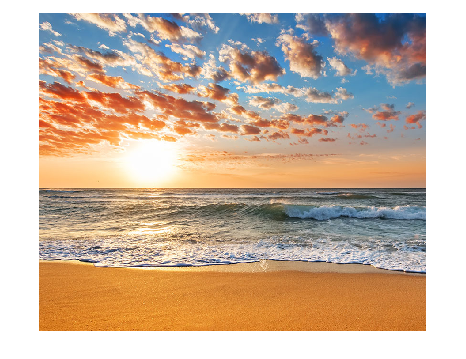

imshow(new_bg)

Perform the composition of extracted foreground object from background 1 and 2 with the new background image

newbgr1 = new_bg(:,:,1)

newbgr1 = 720×876 uint8 matrix
   90   87   86   86   84   85   85   87   89   89   90   90   90   90   89   88   88   86   85   83   80   80   80   81   81   81   80   80   79   79   78   78   78   78   78   77   76   74   74   72   72   72   73   73   74   74   75   74   75   74
   90   89   88   86   85   85   85   87   87   88   89   90   90   89   89   88   89   88   86   85   83   81   81   80   80   80   80   79   79   79   78   78   78   78   78   78   76   75   74   73   73   73   73   73   73   73   74   74   75   74
   91   90   89   87   87   86   85   85   86   87   88   89   89   89   89   89   89   89   88   86   85   83   82   82   80   79   79   79   79   79   78   79   78   79   79   78   77   75   75   73   73   73   72   72   72   73   73   73   73   73
   90   91   91   89   89   87   86   84   84   85   86   87   88   89   89   89   90   90   91   90   89   86   83   83   80   78   78   78   78   78   78   78   78   80   79   79   77   76   75   74   74   74   72 

newbgg1 = new_bg(:,:,2)

newbgg1 = 720×876 uint8 matrix
   134   131   130   130   128   129   129   131   133   133   134   134   134   134   133   132   131   131   130   128   128   128   129   130   130   130   129   129   128   128   127   127   127   127   127   126   126   125   126   125   124   125   127   127   128   128   129   128   129   129
   134   133   132   130   129   129   129   131   131   132   133   134   134   133   133   132   132   131   131   130   130   129   129   129   129   129   129   128   128   128   127   127   127   127   127   127   126   126   126   126   125   125   127   127   127   127   128   128   129   129
   135   134   133   131   131   130   129   129   130   131   132   133   133   133   133   133   132   132   132   131   131   131   130   129   128   128   128   128   128   128   127   128   127   128   128   127   127   126   127   126   125   125   126   126   126   127   127   127   127   127
   134   135   135   133   133   131   130   128   128   129   130

newbgb1 = new_bg(:,:,3)

newbgb1 = 720×876 uint8 matrix
   171   168   167   167   165   166   166   170   172   172   173   173   173   173   172   171   173   172   171   169   168   168   169   170   170   170   169   169   169   169   170   170   170   168   170   169   169   170   170   170   171   171   173   173   174   174   175   174   175   175
   171   170   169   167   166   166   166   169   170   171   172   173   173   172   172   171   174   173   172   171   170   169   169   169   169   169   169   168   169   169   170   170   170   168   170   170   169   170   171   171   172   172   173   173   173   173   174   174   175   175
   172   171   170   168   168   167   166   167   169   170   171   172   172   172   172   172   174   174   174   173   172   171   170   169   168   168   168   168   169   169   170   171   170   169   171   170   170   171   171   171   172   172   172   172   172   173   173   173   173   173
   171   172   172   170   170   168   167   167   167   168   169


newbgr1 = im2double(newbgr1);
newbgg1 = im2double(newbgg1);
newbgb1 = im2double(newbgb1); 

newcr1 = alpha .* Fr1 + (1 - alpha) .* newbgr1; 
newcg1 = alpha .* Fr1 + (1 - alpha) .* newbgg1; 
newcb1 = alpha .* Fr1 + (1 - alpha) .* newbgb1; 

newcr2 = alpha .* Fr1 + (1 - alpha) .* newbgr1; 
newcg2 = alpha .* Fr1 + (1 - alpha) .* newbgg1; 
newcb2 = alpha .* Fr1 + (1 - alpha) .* newbgb1; 


finalgreen = cat(3, newcr1,newcg1,newcb1)

finalgreen = finalgreen(:,:,1) =

    0.3529    0.3412    0.3373    0.3373    0.3294    0.3333    0.3333    0.3412    0.3490    0.3490    0.3529    0.3529    0.3529    0.3529    0.3490    0.3451    0.3451    0.3373    0.3333    0.3255    0.3137    0.3137    0.3137    0.3176    0.3176    0.3176    0.3137    0.3137    0.3098    0.3098    0.3059    0.3059    0.3059    0.3059    0.3059    0.3020    0.2980    0.2902    0.2902    0.2824    0.2824    0.2824    0.2863    0.2863    0.2902    0.2902    0.2941    0.2902    0.2941    0.2902    0.3098    0.3176    0.3176    0.3216    0.3216    0.3176    0.3255    0.3255    0.3255    0.3490    0.3922    0.4784    0.6235    0.7294    0.7020    0.6824    0.8118    0.9059    0.8314    0.7765    0.7373    0.7804    0.8627    0.9373    0.9725    0.9922    0.9569    0.9373    0.9569    0.9647    0.9333    0.8824    0.8314    0.8157    0.8745    0.8941    0.9020    0.9098    0.9020    0.9216    0.9569    0.9922    0.9961    0.9882    0.9882    0.9882    0.

finalorange = cat(3, newcr2,newcg2,newcb2)

finalorange = finalorange(:,:,1) =

    0.3529    0.3412    0.3373    0.3373    0.3294    0.3333    0.3333    0.3412    0.3490    0.3490    0.3529    0.3529    0.3529    0.3529    0.3490    0.3451    0.3451    0.3373    0.3333    0.3255    0.3137    0.3137    0.3137    0.3176    0.3176    0.3176    0.3137    0.3137    0.3098    0.3098    0.3059    0.3059    0.3059    0.3059    0.3059    0.3020    0.2980    0.2902    0.2902    0.2824    0.2824    0.2824    0.2863    0.2863    0.2902    0.2902    0.2941    0.2902    0.2941    0.2902    0.3098    0.3176    0.3176    0.3216    0.3216    0.3176    0.3255    0.3255    0.3255    0.3490    0.3922    0.4784    0.6235    0.7294    0.7020    0.6824    0.8118    0.9059    0.8314    0.7765    0.7373    0.7804    0.8627    0.9373    0.9725    0.9922    0.9569    0.9373    0.9569    0.9647    0.9333    0.8824    0.8314    0.8157    0.8745    0.8941    0.9020    0.9098    0.9020    0.9216    0.9569    0.9922    0.9961    0.9882    0.9882    0.9882    

Display the composition of extracted foreground object from background 1 and 2 with the new background image

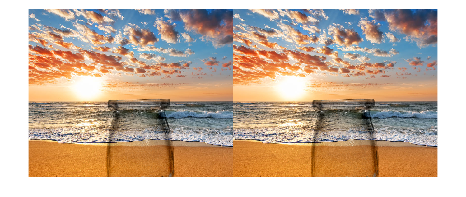

montage({finalgreen, finalorange});